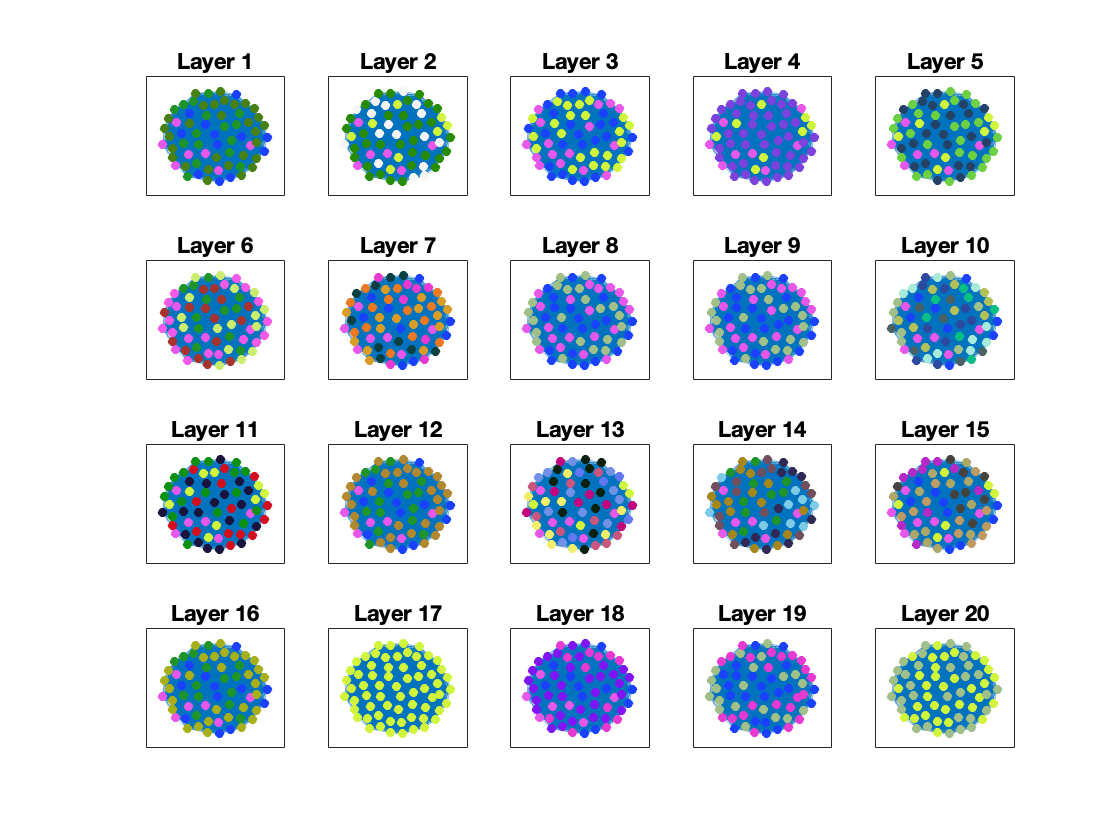

%% Finding MX-ONMTF with modularity density for real networks.
% %for fixed number of common communities, and the number of private and total commmunities per layer.

%this code plots the colors of the cluster labels across all layers

%load("findK_eg2_d5_k6.mat", "kc","k","kp", "Z");

load("findK_eg21_d5_k6.mat", "kc","k","kp", "Z");

%load("fixed_k6_kc3_kpl3", "kc","k","kpl");

Al = importdata("theta_theta_all.mat");


load("notFixed_eg2_d5_k6.mat", "ClustersSupra");

cutoff = median([Z(end-2,3) Z(end-1,3)]);
%dendrogram(Z,'ColorThreshold',cutoff);

kpl=kp;
ClustersSupra = ClustersSupra; %length(unique(ClustersSupra))
k=k;

%un_len = length(unique(ClustersSupra));
un_len = max(ClustersSupra);

colors = random_color(un_len);

L = 20; %20 layers
x=1;
z=64;
y=1;

for cindex=1:L
    
    layer = Al{cindex};
    subplot(4,5,cindex);

    p=plot(graph(layer~=1));
 
    
    labelnode(p,1:64,'') %this removes the node labels
   
    
    hold on
    title(sprintf('Layer %d', cindex));
    
    k_labels = unique(ClustersSupra(x:z));
    
    
    LegendsStrings = cell(length(k_labels),1); % Initialize array  with legends

    %highlight(p,find(ClustersSupra(1:64) == 3), 'NodeColor', 'r')
    %temp = 1;
    
    for index=1:length(k_labels)
        label = k_labels(index);
        col = colors(label,:);

        highlight(p,find(ClustersSupra(x:z) == label), 'NodeColor', col)
    end
    
    x=x+64;
    z=(x+63);
    hold off

end



% figure(1) %image of data
% 
% % Loop over each layer
% for i = 1:L
%     % Get the current layer
%     layer = Al{i};
%     % Plot the layer
% 
%     %figure;
%     subplot(4,5,i);
%     imagesc(layer);
%     axis square;
%     colormap(gray);
%     title(sprintf('Layer %d', i));
% end


%figure(2)
